# Compute and Display Hough Transform

Read an image, and convert it to a grayscale image.

clear all; close all; clc

npeaks = 8;

RGB = imread('gantrycrane.png');
I  = rgb2gray(RGB);

Extract edges.

BW = edge(I,'canny');

Calculate Hough transform.

[H,T,R] = hough(BW,'RhoResolution',1,'Theta',-90:1:89);

Display the original image and the Hough matrix.

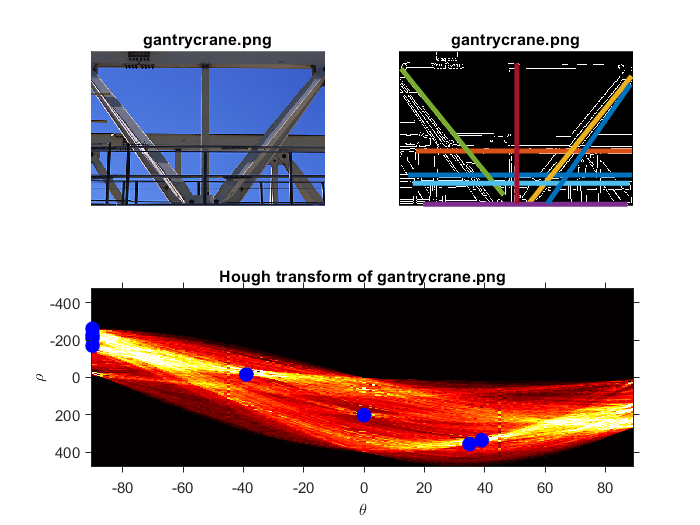

subplot(2,2,1);
imshow(RGB);
title('gantrycrane.png');

subplot(2,2,2);
imshow(BW);
title('gantrycrane.png');

subplot(2,2,3:4);
imshow(imadjust(rescale(H)),'XData',T,'YData',R,...
      'InitialMagnification','fit');
title('Hough transform of gantrycrane.png');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal, hold on;
colormap(gca,hot);


P = houghpeaks(H,npeaks);

plot(T(P(:,2)),R(P(:,1)),'b.','markersize',30);
lines = houghlines(BW,T,R,P,'FillGap',1000,'MinLength',1); % Fillgap is arbitrarily large and Minlength is arbitrarily small

subplot(2,2,2); hold on

for i = 1:length(lines)
lines_out = [lines(i).point1 lines(i).point2];
plot([lines_out(1,1) lines_out(1,3)],[lines_out(1,2) lines_out(1,4)],'LineWidth',3)
end

*Copyright 2012 The MathWorks, Inc.*